Forward kinematic:

syms theta1 theta2 theta3 theta4 theta5 theta6
a1 = [50*cos(theta1); 50*sin(theta1); 380]

$$a1 = \left(\begin{array}{c} 50\,\cos\left(\theta_{1}\right)\\ 50\,\sin\left(\theta_{1}\right)\\ 380 \end{array}\right)$$

a2 = [420*cos(theta2); 420*sin(theta2); 0]

$$a2 = \left(\begin{array}{c} 420\,\cos\left(\theta_{2}\right)\\ 420\,\sin\left(\theta_{2}\right)\\ 0 \end{array}\right)$$

a3 = [25*cos(theta3); 25*sin(theta3); 0]

$$a3 = \left(\begin{array}{c} 25\,\cos\left(\theta_{3}\right)\\ 25\,\sin\left(\theta_{3}\right)\\ 0 \end{array}\right)$$

a4 = [0; 0; 440]

a4 =      0
     0
   440


a5 = [0; 0; 0]

a5 =      0
     0
     0


a6 = [0; 0; 98]

a6 =      0
     0
    98


Q1 = [cos(theta1) 0 sin(theta1);
      sin(theta1) 0 -cos(theta1);
      0           1      0]

$$Q1 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right)\\ 0 & 1 & 0 \end{array}\right)$$

Q2 = [cos(theta2) -sin(theta2) 0;
      sin(theta2) cos(theta2) 0;
      0              0       1]

$$Q2 = \left(\begin{array}{ccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


Q3 = [cos(theta3)   0    sin(theta3);
      sin(theta3)   0   -cos(theta3);
      0             0          1]

$$Q3 = \left(\begin{array}{ccc} \cos\left(\theta_{3}\right) & 0 & \sin\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & 0 & -\cos\left(\theta_{3}\right)\\ 0 & 0 & 1 \end{array}\right)$$

Q4 = [cos(theta4) 0 sin(theta4);
      sin(theta4) 0 -cos(theta4);
      0           1        0]

$$Q4 = \left(\begin{array}{ccc} \cos\left(\theta_{4}\right) & 0 & \sin\left(\theta_{4}\right)\\ \sin\left(\theta_{4}\right) & 0 & -\cos\left(\theta_{4}\right)\\ 0 & 1 & 0 \end{array}\right)$$

Q5 = [cos(theta5) 0 sin(theta5);
      sin(theta5) 0 -cos(theta5);
      0           1       0]

$$Q5 = \left(\begin{array}{ccc} \cos\left(\theta_{5}\right) & 0 & \sin\left(\theta_{5}\right)\\ \sin\left(\theta_{5}\right) & 0 & -\cos\left(\theta_{5}\right)\\ 0 & 1 & 0 \end{array}\right)$$

Q6 = [cos(theta6) -sin(theta6) 0;
      sin(theta6) cos(theta6)  0;
      0                0       1]

$$Q6 = \left(\begin{array}{ccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0\\ \sin\left(\theta_{6}\right) & \cos\left(\theta_{6}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

P = a1+Q1*a2+Q1*Q2*a3+Q1*Q2*Q3*a4+Q1*Q2*Q3*a4+Q1*Q2*Q3*Q4*a5+Q1*Q2*Q3*Q4*Q5*a6

orinetation = Q1*Q2*Q3*Q4*Q5*Q6

x = P(1)

$$x = 50\,\cos\left(\theta_{1}\right)+880\,\sin\left(\theta_{1}\right)+420\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-98\,\cos\left(\theta_{5}\right)\,\left(\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)-25\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-98\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\right)+25\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)+880\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+880\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)$$

y = P(2)

$$y = 50\,\sin\left(\theta_{1}\right)-880\,\cos\left(\theta_{1}\right)+420\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-98\,\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)+880\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+880\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-25\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-98\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\right)+25\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)$$

simplify(expand((x^2)+(y^2)))

DH:

dhparams = [0.050   pi/2	0.380   pi/2;
            0.420    0       0      0;
            0.025  	pi/2	0   	pi/2;
            0   	pi/2	0.440 	0;
            0       pi/2	0   	0;
            0       0       0.098   0]

dhparams =     0.0500    1.5708    0.3800    1.5708
    0.4200         0         0         0
    0.0250    1.5708         0    1.5708
         0    1.5708    0.4400         0
         0    1.5708         0         0
         0         0    0.0980         0


Simulation:

robot = rigidBodyTree;
bodies = cell(6,1);
joints = cell(6,1);
for i = 1:6
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robot,bodies{i},bodies{i-1}.Name)
    end
end
showdetails(robot)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


Interactive GUI:

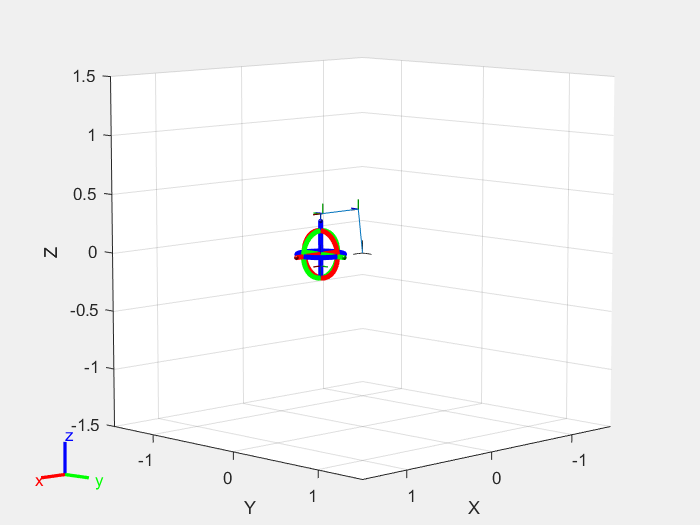

gui = interactiveRigidBodyTree(robot);

randConfig = robot.randomConfiguration;
tform = getTransform(robot,randConfig,'body6', 'base');
ik = inverseKinematics('RigidBodyTree',robot);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = robot.homeConfiguration;
[configSoln,solnInfo] = ik('body6',tform,weights,randConfig);

Inverse Kinematic Problem:

configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


Evaluation:

tform_wrist = getTransform(robot,randConfig,'body4', 'base');
xc = tform_wrist(1,4);
yc = tform_wrist(2,4);
zc = tform_wrist(3,4);
t1 = atan(yc/xc)

t1 = 0.6986

t1p = t1 - pi

t1p = -2.4430

t1pp = t1 + pi

t1pp = 3.8402

tform_body2 = getTransform(robot,randConfig,'body2', 'base');
d1 = tform_body2(3,4);
D = ((xc^2)+(yc^2)+((zc-d1)^2)-(0.44^2)-(0.38^2))/(2*0.44*0.38)

D = -0.7767

t3 = atan2(D, sqrt(1-D^2))

t3 = -0.8895

t3-pi

ans = -4.0311

t2 = atan2(-sqrt(xc^2+yc^2), zc-d1)-atan2((0.38)+(0.42)*cos(configSoln(3).JointPosition), 0.42*sin(configSoln(3).JointPosition))

t2 = -3.0055

tform_3to6 = getTransform(robot,randConfig,'body6', 'body3');
R_3to6 = tform_3to6(1:3, 1:3);
if sin(configSoln(5).JointPosition)<0
    t4 = atan2(-R_3to6(2,3), -R_3to6(1,3))
    t5 = atan2(sqrt((R_3to6(1,3)^2)+(R_3to6(2,3)^2)), -R_3to6(3,3))
    t5neg = -t5
    t6 = atan2(R_3to6(3,2), -R_3to6(3,1))
end

t4 = -0.4979

t5 = 1.1845

t5neg = -1.1845

t6 = 1.2180

if sin(configSoln(5).JointPosition)>0
    t4 = atan2(R_3to6(2,3),R_3to6(1,3))
    t5 = atan2(sqrt((R_3to6(1,3)^2)+(R_3to6(2,3)^2)), -R_3to6(3,3))
    t5neg = atan2(-sqrt((R_3to6(1,3)^2)+(R_3to6(2,3)^2)), R_3to6(3,3))
    t6 = -atan2(R_3to6(3,2), R_3to6(3,1))
end